# 8 Furuta Pendulum - Controller Tuning Steps

## 1. Tuning Rules and Starting Point

This is a small teaching search, not a repeat of the historical 720-point PID or 480-point LQR search. Start from the accepted design. Change a small number of parameters, check stability, compare the same test, and shortlist candidates. A good linear score is not enough to accept a new nonlinear controller. Nothing here overwrites Accepted_Controller_Data.mat or the six existing result files.

assert(isfolder('data') && isfolder('models'),'Set Current Folder to Furuta_Clean_Project.');
addpath('models','geometry');
load('data/Linear_Model_Data.mat');
load('data/Accepted_Controller_Data.mat');
accepted_PID=PID;accepted_Q=Q;accepted_R=Rcost;
xe=x_equilibrium;taue=tau_equilibrium;
t=(0:0.001:10)';d=0.01*double(t>=1 & t<1.05);
assert(rank(ctrb(A,B))==4 && rank(obsv(A,C))==4);


## 2. Common Targets and Ranking

First reject unstable candidates. Nominal limits are pendulum peak <=8 deg, arm excursion <=90 deg, pendulum settling <=2.5 s, arm settling <=8 s, and peak torque <=0.0095 N m. The torque target leaves 5 percent of the 0.01 N m cap. Rank feasible designs using 35 percent IAE, 25 percent RMS torque rate, 20 percent RMS torque, 10 percent arm acceleration and 10 percent arm excursion. Fixed reference values normalize the units. This score is a tuning choice, not the LQR cost J.

targets=table([8;90;2.5;8;0.0095], ...
    'RowNames',{'Pendulum peak deg','Arm excursion deg','Pendulum settling s', ...
    'Arm settling s','Peak torque N m'},'VariableNames',{'Limit'})

targets = 5×1 table
                           Limit 
                           ______

    Pendulum peak deg           8
    Arm excursion deg          90
    Pendulum settling s       2.5
    Arm settling s              8
    Peak torque N m        0.0095


## 3. PID: Shape P and D First

Try a small P/D grid around the accepted design. Keep the existing coordinate signs. Scale the arm and pendulum P terms together, then the D terms together. Keep the integral gain fixed in this first stage and check all five augmented poles.

PID_candidates={};PID_screen=table;id=0;
for pScale=[0.9,1,1.1]
    for dScale=[0.9,1,1.1]
        id=id+1;candidate=accepted_PID;
        candidate.ArmP=pScale*accepted_PID.ArmP;candidate.PendP=pScale*accepted_PID.PendP;
        candidate.ArmD=dScale*accepted_PID.ArmD;candidate.PendD=dScale*accepted_PID.PendD;
        PID_candidates{id}=candidate;
        row=linear_trial(A,B,'PID',candidate,t,d);
        row.CandidateID=id;row.Pscale=pScale;row.Dscale=dScale;row.ArmI=candidate.ArmI;
        PID_screen=[PID_screen;row];
    end
end
PID_PD_ranking=rank_candidates(PID_screen)

PID_PD_ranking = 9×13 table
    Stable    Feasible     Score     PeakPendulum_deg    PendulumSettling_s    ArmSettling_s    PeakTorque_Nm    PendulumIAE_rad_s    RmsTorque_Nm    CandidateID    Pscale    Dscale     ArmI 
    ______    ________    _______    ________________    __________________    _____________    _____________    _________________    ____________    ___________    ______    ______    ______

    true       true       0.93127         2.6857               0.897               6.695          0.0093966          0.013186          0.00068235

assert(any(PID_PD_ranking.Feasible),'No feasible PID candidate; review the gain range.');


## 4. PID: Tune Integral Action Separately

Use the best feasible P/D candidate as a starting point. Try three nearby integral gains. More integral action can reduce constant-load error but can also slow arm recovery or cause saturation. These pulse tests do not replace a constant-load test. The nonlinear block keeps its existing +/-0.002 N m integral limit.

best_PD=PID_candidates{PID_PD_ranking.CandidateID(1)};
for iScale=[0.5,1,1.5]
    id=id+1;candidate=best_PD;candidate.ArmI=iScale*accepted_PID.ArmI;
    PID_candidates{id}=candidate;row=linear_trial(A,B,'PID',candidate,t,d);
    row.CandidateID=id;row.Pscale=candidate.ArmP/accepted_PID.ArmP;
    row.Dscale=candidate.ArmD/accepted_PID.ArmD;row.ArmI=candidate.ArmI;
    PID_screen=[PID_screen;row];
end
PID_ranking=rank_candidates(PID_screen)

PID_ranking = 12×13 table
    Stable    Feasible     Score     PeakPendulum_deg    PendulumSettling_s    ArmSettling_s    PeakTorque_Nm    PendulumIAE_rad_s    RmsTorque_Nm    CandidateID    Pscale    Dscale     ArmI  
    ______    ________    _______    ________________    __________________    _____________    _____________    _________________    ____________    ___________    ______    ______    _______

    true       true       0.92764         2.6856               0.904               7.787          0.0093969          0.013024          0.00068223

PID_shortlist=PID_candidates{PID_ranking.CandidateID(1)};


## 5. Pole Placement: Compare Pole Sets

Choose pole sets from the required response speed, then calculate K with place(). Faster poles may require more torque and may perform worse after saturation. These are the nine sets documented in the earlier project. Recompute their linear responses here; the historical nonlinear winner does not automatically win every new test.

pole_sets={[-2 -3 -5 -7],[-1.5 -2.5 -4 -6],[-2.5 -4 -6 -9], ...
    [-3 -4 -6 -8],[-4 -5 -7 -9],[-5 -6 -8 -10], ...
    [-3+3i -3-3i -6 -8],[-4+4i -4-4i -7 -9],[-1 -4 -7 -10]};
PP_screen=table;PP_gains=zeros(9,4);
for id=1:numel(pole_sets)
    K=place(A,B,pole_sets{id});PP_gains(id,:)=K;
    row=linear_trial(A,B,'Pole Placement',K,t,d);
    row.CandidateID=id;row.DesiredPoles=string(mat2str(pole_sets{id},3));
    PP_screen=[PP_screen;row];
end
PP_ranking=rank_candidates(PP_screen)

PP_ranking = 9×11 table
    Stable    Feasible    Score     PeakPendulum_deg    PendulumSettling_s    ArmSettling_s    PeakTorque_Nm    PendulumIAE_rad_s    RmsTorque_Nm    CandidateID        DesiredPoles     
    ______    ________    ______    ________________    __________________    _____________    _____________    _________________    ____________    ___________    _____________________

    true       true       1.0097         3.0515               1.308               1.338          0.0087964          0.017003           0.0006954          6         "[-5 -6 -8 -10]"     
    true       true       1.1671         3.

assert(any(PP_ranking.Feasible),'No feasible Pole Placement candidate.');
PP_shortlist=PP_gains(PP_ranking.CandidateID(1),:);


## 6. LQR: Vary Q and Keep R Fixed

Use the accepted normalized Q/R as a reference. Vary the arm-angle and pendulum-angle weights by factors of 0.5, 1 and 2. Keep the velocity weights and R fixed. For each Q, solve LQR, check the closed-loop poles and rank the same pulse test. Increasing a Q weight expresses a stronger cost on that state; it does not guarantee a better saturated response.

LQR_screen=table;LQR_gains=zeros(9,4);LQR_weights=cell(9,1);id=0;
for armScale=[0.5,1,2]
    for pendScale=[0.5,1,2]
        id=id+1;trial_Q=accepted_Q;
        trial_Q(1,1)=armScale*accepted_Q(1,1);trial_Q(2,2)=pendScale*accepted_Q(2,2);
        K=lqr(A,B,trial_Q,accepted_R);LQR_gains(id,:)=K;LQR_weights{id}=trial_Q;
        row=linear_trial(A,B,'LQR',K,t,d);
        row.CandidateID=id;row.ArmQscale=armScale;row.PendQscale=pendScale;
        LQR_screen=[LQR_screen;row];
    end
end
LQR_ranking=rank_candidates(LQR_screen)

LQR_ranking = 9×12 table
    Stable    Feasible     Score     PeakPendulum_deg    PendulumSettling_s    ArmSettling_s    PeakTorque_Nm    PendulumIAE_rad_s    RmsTorque_Nm    CandidateID    ArmQscale    PendQscale
    ______    ________    _______    ________________    __________________    _____________    _____________    _________________    ____________    ___________    _________    __________

    true       true       0.94184         2.6734               1.385               1.372          0.0094747          0.013436          0.00067991          5              1            1    

assert(any(LQR_ranking.Feasible),'No feasible LQR candidate.');
LQR_shortlist=LQR_gains(LQR_ranking.CandidateID(1),:);


## 7. Save the Linear Screens

The top rows are shortlists for further tests, not approved replacements. Preserve every candidate table so the decision is reviewable. The accepted gains stay unchanged.

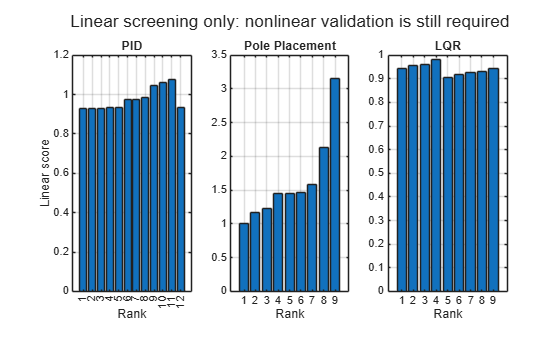

save('results/Tuning_Linear_Screens.mat','PID_screen','PID_ranking','PID_candidates', ...
    'PP_screen','PP_ranking','PP_gains','pole_sets','LQR_screen','LQR_ranking', ...
    'LQR_gains','LQR_weights','PID_shortlist','PP_shortlist','LQR_shortlist');
writetable(PID_ranking,'results/Tuning_PID_Linear.csv');
writetable(PP_ranking,'results/Tuning_PP_Linear.csv');
writetable(LQR_ranking,'results/Tuning_LQR_Linear.csv');
figure('Name','Tuning linear screens','Color','w');tiledlayout(1,3);
nexttile;bar(PID_ranking.Score);title('PID');ylabel('Linear score');xlabel('Rank');grid on;
nexttile;bar(PP_ranking.Score);title('Pole Placement');xlabel('Rank');grid on;
nexttile;bar(LQR_ranking.Score);title('LQR');xlabel('Rank');grid on;
sgtitle('Linear screening only: nonlinear validation is still required');
drawnow;exportgraphics(gcf,'results/Tuning_Linear_Screens.png','Resolution',140);

## 8. Optional Nonlinear Checks and Acceptance

Set run_nonlinear_checks to true to test each shortlist on the saved nonlinear plant with +0.01 and +0.02 N m pulses. This is optional because it adds six simulations. The helper sets the actual pulse, cap, equilibrium and candidate gains explicitly on a temporary model. A failed strong test rejects that candidate; it does not justify silently changing the torque limit. Before adopting a design, also test the negative pulse, initial tilt, constant load, uncertainty and practical arm-travel limits. No accepted gain file is overwritten.

run_nonlinear_checks=true;
nonlinear_trials=table;
if run_nonlinear_checks
    choices={'PID','Pole Placement','LQR'};
    shortlists={PID_shortlist,PP_shortlist,LQR_shortlist};
    for k=1:3
        for amplitude=[0.01,0.02]
            row=nonlinear_trial(choices{k},shortlists{k},xe,taue,amplitude);
            nonlinear_trials=[nonlinear_trials;row];
        end
    end
    nonlinear_trials
    save('results/Tuning_Nonlinear_Checks.mat','nonlinear_trials');
    writetable(nonlinear_trials,'results/Tuning_Nonlinear_Checks.csv');
else
    disp('Nonlinear tuning checks skipped. Linear shortlists are not new accepted gains.');
end

nonlinear_trials = 6×10 table
       Controller       Pulse_Nm    PeakPendulum_deg    PeakArm_deg    PendulumSettling_s    ArmSettling_s    PeakTorque_Nm    SaturationFraction    FinalPendulum_deg    PassesTestLimits
    ________________    ________    ________________    ___________    __________________    _____________    _____________    __________________    _________________    ________________

    "PID"                 0.01           2.6871           14.559             0.904               7.814          0.0094045                 0             0.00016406             true       
    "PID"                 0.02           9.1784           95.267    

%% Selected Candidate Gains

disp('PID candidate gains:')

PID candidate gains:


disp(PID_shortlist)

     ArmP: 0.0020
     ArmD: 0.0028
    PendP: 0.1151
    PendD: 0.0097
     ArmI: 3.5000e-04
      Kaw: 20




disp('Pole Placement candidate gains:')

Pole Placement candidate gains:


disp(PP_shortlist)

   -0.0026    0.1046   -0.0022    0.0078




disp('LQR candidate gains:')

LQR candidate gains:


disp(LQR_shortlist)

   -0.0028    0.1227   -0.0023    0.0089




%% Local Functions
function [row,K]=linear_trial(A,B,kind,gain,t,d)
% Reject unstable candidates before simulating the unsaturated linear model.
if strcmp(kind,'PID')
    p=gain;L=[p.ArmP,-p.PendP,p.ArmD,-p.PendD];
    Acl=[A+B*L,B;p.ArmI,0,0,0,0];Bd=[B;0];K=NaN(1,4);
else
    K=gain;Acl=A-B*K;Bd=B;
end
stable=all(real(eig(Acl))<0);
if ~stable
    row=table(false,false,Inf,NaN,Inf,Inf,NaN,NaN,NaN, ...
        'VariableNames',{'Stable','Feasible','Score','PeakPendulum_deg', ...
        'PendulumSettling_s','ArmSettling_s','PeakTorque_Nm','PendulumIAE_rad_s','RmsTorque_Nm'});
    return
end
x=lsim(ss(Acl,Bd,eye(size(Acl,1)),zeros(size(Acl,1),1)),d,t);
if strcmp(kind,'PID'),u=x(:,1:4)*L'+x(:,5);else,u=-x*K';end
peak=max(abs(rad2deg(x(:,2))));armPeak=max(abs(rad2deg(x(:,1))));
ts=settle(t,x(:,2),deg2rad(0.1),1.05);armTs=settle(t,x(:,1),deg2rad(1),1.05);
peakU=max(abs(u));rmsU=sqrt(trapz(t,u.^2)/10);iae=trapz(t,abs(x(:,2)));
rmsRate=sqrt(trapz(t,gradient(u,t).^2)/10);accel=max(abs(gradient(x(:,3),t)));
feasible=peak<=8 && armPeak<=90 && ts<=2.5 && armTs<=8 && peakU<=0.0095;
score=0.35*iae/0.016+0.25*rmsRate/0.015+0.20*rmsU/0.0007 ...
    +0.10*accel/65+0.10*armPeak/18.43;
row=table(stable,feasible,score,peak,ts,armTs,peakU,iae,rmsU, ...
    'VariableNames',{'Stable','Feasible','Score','PeakPendulum_deg', ...
    'PendulumSettling_s','ArmSettling_s','PeakTorque_Nm','PendulumIAE_rad_s','RmsTorque_Nm'});
end

function ranking=rank_candidates(screen)
ranking=sortrows(screen,{'Feasible','Score'},{'descend','ascend'});
end

function value=settle(t,y,band,start)
outside=find(t>=start & abs(y)>band);
if isempty(outside),value=0;
elseif outside(end)==numel(t),value=Inf;
else,value=t(outside(end)+1)-start;
end
end

function row=nonlinear_trial(kind,gain,xe,taue,amplitude)
% Each trial starts a fresh saved-plant simulation with explicit test settings.
assert(~bdIsLoaded('Furuta_Tuning_Trial'),'Close the earlier temporary tuning model first.');
folder=tempname;mkdir(folder);model='Furuta_Tuning_Trial';
copyfile(fullfile(pwd,'models','Furuta_StudyF.slx'),fullfile(folder,[model '.slx']));
load_system(fullfile(folder,[model '.slx']));cleanup=onCleanup(@()close_system(model,0));
in=Simulink.SimulationInput(model);
in=in.setModelParameter('StopTime','10');
in=in.setBlockParameter([model '/Measured states'],'OpenAtSimulationStart','off');
in=in.setBlockParameter([model '/Applied torque Nm'],'OpenAtSimulationStart','off');
in=in.setBlockParameter([model '/Controller selector'],'controller_choice',kind);
in=in.setBlockParameter([model '/Pulse starts'],'Time','1');
in=in.setBlockParameter([model '/Pulse starts'],'Before','0');
in=in.setBlockParameter([model '/Pulse starts'],'After',num2str(amplitude,17));
in=in.setBlockParameter([model '/Pulse ends'],'Time','1.05');
in=in.setBlockParameter([model '/Pulse ends'],'Before','0');
in=in.setBlockParameter([model '/Pulse ends'],'After',num2str(-amplitude,17));
in=in.setVariable('tau_limit_sim',0.01,'Workspace',model);
in=in.setVariable('xe_controller',xe,'Workspace',model);
in=in.setVariable('taue_controller',taue,'Workspace',model);
if strcmp(kind,'PID')
    fields={'ArmP','ArmI','ArmD','PendP','PendD'};
    for j=1:numel(fields),in=in.setVariable(['pid_' fields{j}],gain.(fields{j}),'Workspace',model);end
elseif strcmp(kind,'Pole Placement')
    in=in.setVariable('K_pp_controller',gain,'Workspace',model);
else
    in=in.setVariable('K_lqr_controller',gain,'Workspace',model);
end
raw=sim(in);xs=raw.x_simscape;us=raw.tau_controller;t=(0:0.001:10)';
[tx,ix]=unique(xs.Time);[tu,iu]=unique(us.Time);
x=interp1(tx,xs.Data(ix,:),t,'pchip')-xe';u=interp1(tu,us.Data(iu,:),t,'pchip');
assert(all(isfinite(x(:)))&&all(isfinite(u)),'Incomplete nonlinear trial.');
row=table(string(kind),amplitude,max(abs(rad2deg(x(:,2)))), ...
    max(abs(rad2deg(x(:,1)))), ...
    settle(t,x(:,2),deg2rad(0.1),1.05),settle(t,x(:,1),deg2rad(1),1.05), ...
    max(abs(u)),trapz(t,double(abs(u)>=0.01*(1-1e-6)))/10, ...
    abs(rad2deg(x(end,2))), ...
    'VariableNames',{'Controller','Pulse_Nm','PeakPendulum_deg','PeakArm_deg','PendulumSettling_s', ...
    'ArmSettling_s','PeakTorque_Nm','SaturationFraction','FinalPendulum_deg'});
if amplitude<=0.01
    row.PassesTestLimits=row.PeakPendulum_deg<=8 && row.PendulumSettling_s<=2.5 ...
        && row.ArmSettling_s<=8 && row.PeakTorque_Nm<=0.0095 && row.SaturationFraction==0;
else
    row.PassesTestLimits=row.PeakPendulum_deg<=20 && row.PendulumSettling_s<=5 ...
        && row.ArmSettling_s<=9 && row.FinalPendulum_deg<=0.01;
end
end
